N = 80;
M = 12800;
deltaT = 1/M;
deltaX = 1/N;

x = linspace(0, 1, N + 1);
t = linspace(0, 1, M + 1);

[X, T] = meshgrid(x, t);

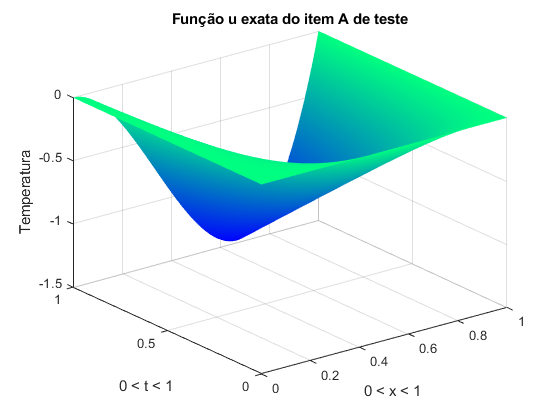

% 1A Teste
uReal = (10 .* X .* X .* (X - 1) .* T);

figure(1)
surf(x, t, uReal)
title('Função u exata do item A de teste')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('winter')
shading interp

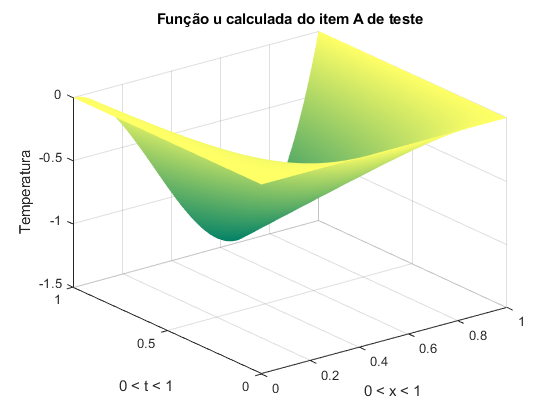


figure(2)
R1aT = readmatrix('Output1ATeste.txt');
R1aT(:,end) = [];
surf(x, t, R1aT)
title('Função u calculada do item A de teste')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('summer')
shading interp

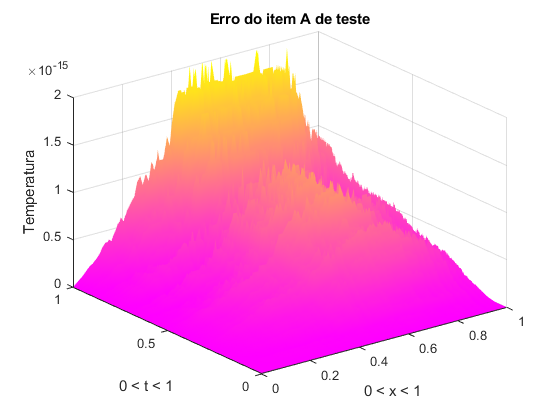


figure(3)
erro1aT = readmatrix('Erro1ATeste.txt');
erro1aT(:,end) = [];
surf(x, t, erro1aT)
title('Erro do item A de teste')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('spring')
shading interp

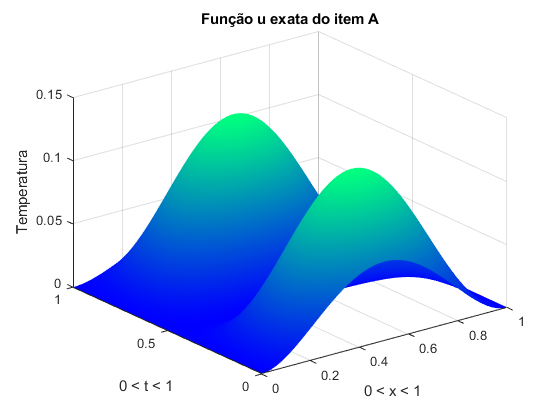

% 1A Real
uReal = ((1 + sin(10 .* T)) .* X .* X .* (1 - X) .* (1 - X));

figure(1)
surf(x, t, uReal)
title('Função u exata do item A')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
shading interp

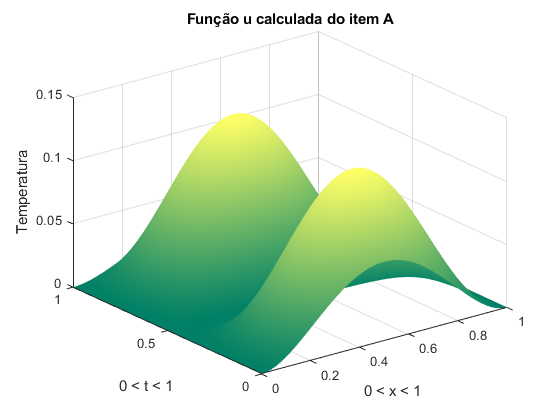


figure(2)
R1a = readmatrix('Output1A.txt');
R1a(:,end) = [];
surf(x, t, R1a)
title('Função u calculada do item A')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('summer')
shading interp

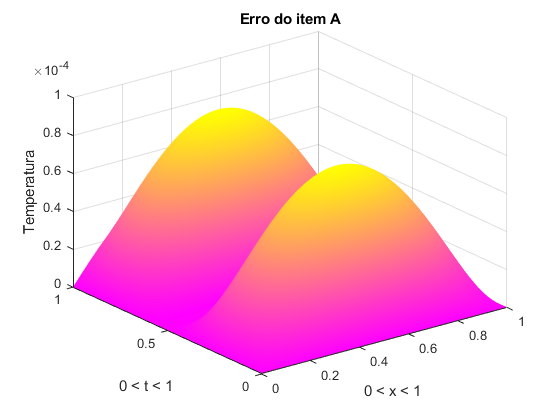


figure(3)
erro1a = readmatrix('Erro1A.txt');
erro1a(:,end) = [];
surf(x, t, erro1a)
title('Erro do item A')
xlabel('0 < x < 1')
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('spring')
shading interp


figure(4)
hold

Current plot held


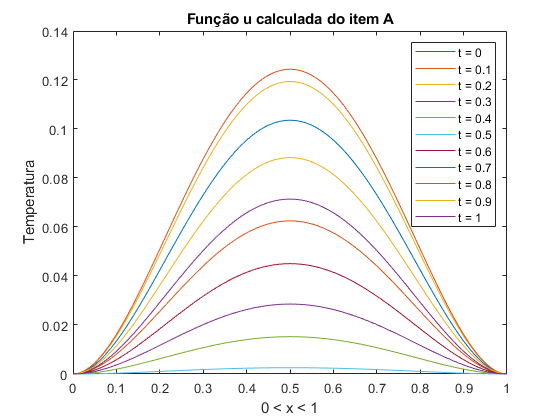

distancia = floor(M/10);
Ratual = R1a(1, :);
plot(x, Ratual)
for v = 2:10
   Ratual = R1a(1+v*distancia, :);
   plot(x, Ratual)
end
legend('t = 0','t = 0.1','t = 0.2','t = 0.3','t = 0.4','t = 0.5', 't = 0.6', 't = 0.7', 't = 0.8', 't = 0.9', 't = 1')
title('Função u calculada do item A')
xlabel('0 < x < 1') 
ylabel('Temperatura')

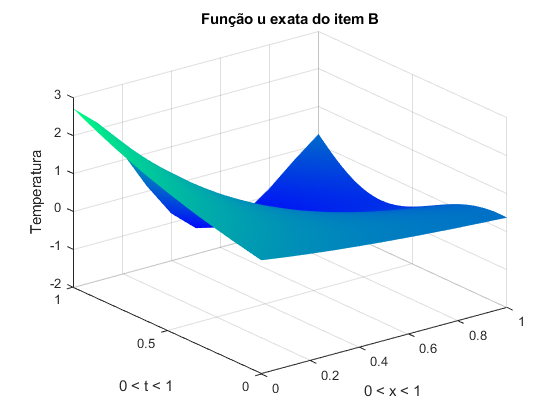

% 1B
uReal = (exp(T - X) .* cos(5 .* T .* X));

figure(1)
surf(x, t, uReal)
title('Função u exata do item B')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
shading interp

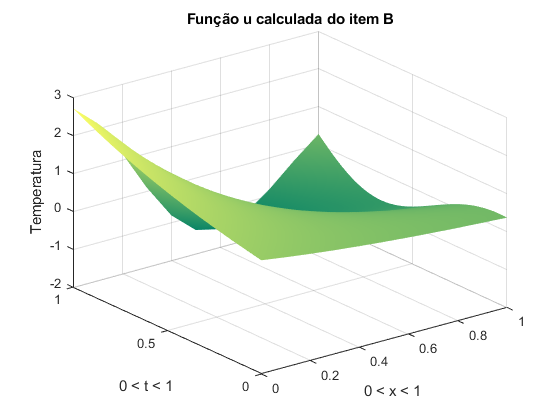


figure(2)
R1b = readmatrix('Output1B.txt');
R1b(:,end) = [];
surf(x, t, R1b)
title('Função u calculada do item B')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('summer')
shading interp

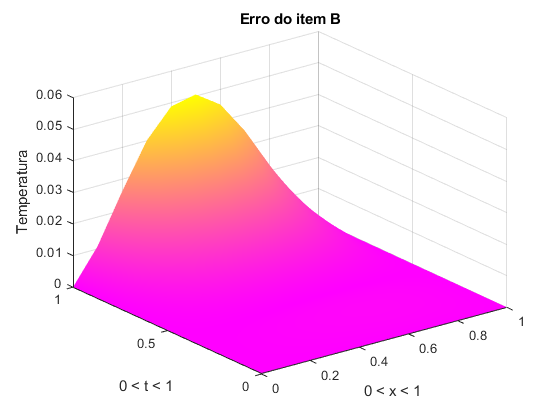


figure(3)
erro1b = readmatrix('Erro1B.txt');
erro1b(:,end) = [];
surf(x, t, erro1b)
title('Erro do item B')
xlabel('0 < x < 1')
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('spring')
shading interp


figure(4)
hold
distancia = floor(M/10);
Ratual = R1b(1, :);
plot(x, Ratual)
for v = 2:10
   Ratual = R1b(1+v*distancia, :);
   plot(x, Ratual)
end
legend('t = 0','t = 0.1','t = 0.2','t = 0.3','t = 0.4','t = 0.5', 't = 0.6', 't = 0.7', 't = 0.8', 't = 0.9', 't = 1')
title('Função u calculada do item B')
xlabel('0 < x < 1') 
ylabel('Temperatura')

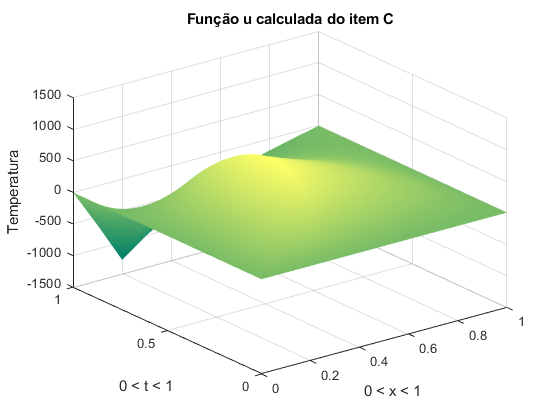

% 1C

R1c = readmatrix('Output1C.txt');
R1c(:,end) = [];
surf(x, t, R1c)
title('Função u calculada do item C')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('summer')
shading interp



figure(4)
hold
distancia = floor(M/10);
Ratual = R1c(1, :);
plot(x, Ratual)
for v = 2:10
   Ratual = R1c(1+v*distancia, :);
   plot(x, Ratual)
end
legend('t = 0','t = 0.1','t = 0.2','t = 0.3','t = 0.4','t = 0.5', 't = 0.6', 't = 0.7', 't = 0.8', 't = 0.9', 't = 1')
title('Função u calculada do item C')
xlabel('0 < x < 1') 
ylabel('Temperatura')

N_M = 10;
x = linspace(0, 1, N_M + 1);
t = linspace(0, 1, N_M + 1);

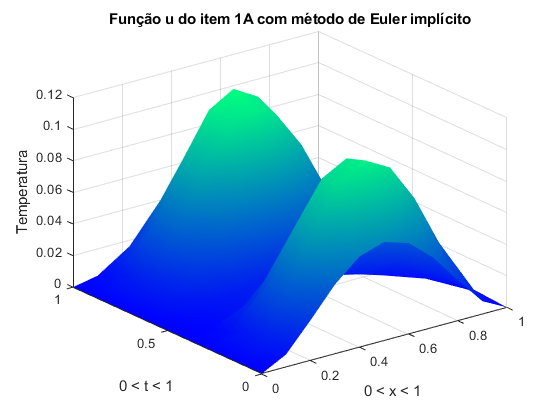

% 2B
R2b = readmatrix('Output2B.txt', 'CommentStyle',{'='});
R2b(:,end) = [];

R2b1 = R2b(2:N_M+2,:);
figure(1)
surf(x, t, R2b1)
title('Função u do item 1A com método de Euler implícito')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
shading interp

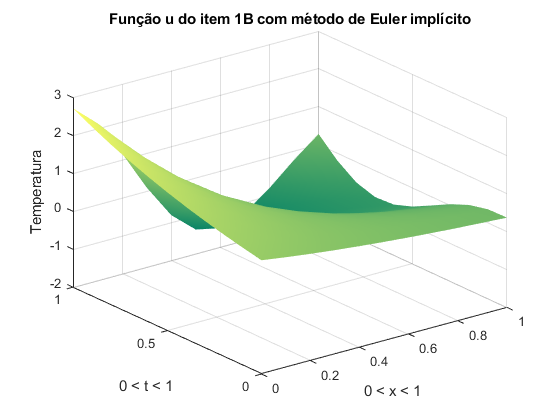


R2b2 = R2b(N_M+4:2*N_M+4,:);
figure(2)
surf(x, t, R2b2)
title('Função u do item 1B com método de Euler implícito')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('summer')
shading interp

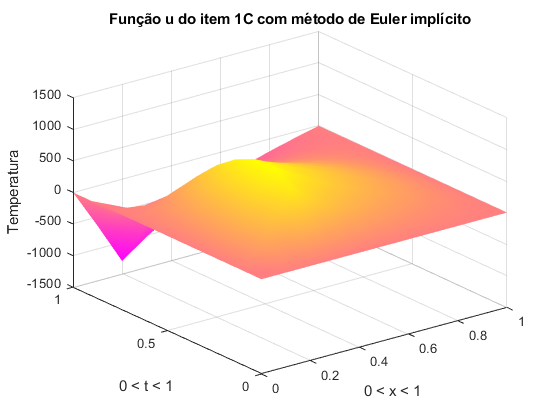


R2b3 = R2b(2*N_M+6:3*N_M+6,:);
figure(3)
surf(x, t, R2b3)
title('Função u do item 1C com método de Euler implícito')
xlabel('0 < x < 1')
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('spring')
shading interp

N_M = 200;
x = linspace(0, 1, N_M + 1);
t = linspace(0, 1, N_M + 1);

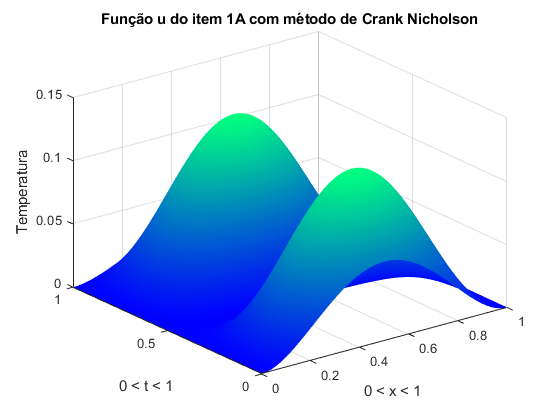

% 2C
R2c = readmatrix('Output2C.txt', 'CommentStyle',{'='});
R2c(:,end) = [];

R2c1 = R2c(2:N_M+2,:);
figure(1)
surf(x, t, R2c1)
title('Função u do item 1A com método de Crank Nicholson')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
shading interp

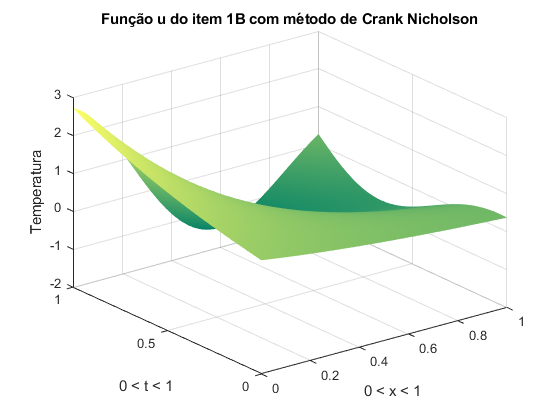


R2c2 = R2c(N_M+4:2*N_M+4,:);
figure(2)
surf(x, t, R2c2)
title('Função u do item 1B com método de Crank Nicholson')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('summer')
shading interp

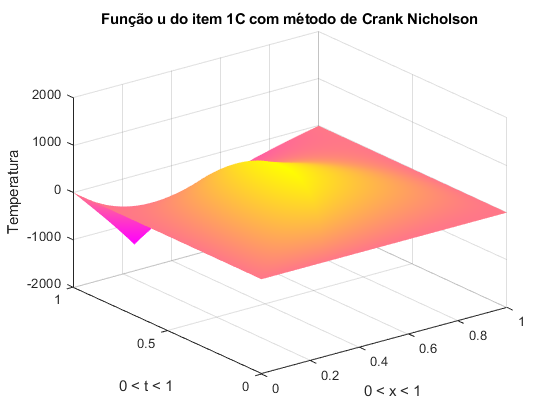


R2c3 = R2c(2*N_M+6:3*N_M+6,:);
figure(3)
surf(x, t, R2c3)
title('Função u do item 1C com método de Crank Nicholson')
xlabel('0 < x < 1')
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('spring')
shading interp